# FacTRK Circular Deblurring Experiments using MRI Data

clear;clc;close all;
addpath('../tproduct toolbox 2.0 (transform)/')

%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              %takes only first 12 frames   
[m,n,p] = size(X);                    %m1 = 128, n1 = 128, p = 12

%Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
g = fspecial('average',[5,5]);
[m1,n1] = size(h);   
[m2,n2] = size(g);

%Building circularly blurred images

Y = zeros(m,n,p);
for i = 1:p
    temp = blurryimage(X(:,:,i), h, [m,n]);
    Y(:,:,i) = blurryimage(temp, g, [m,n]);
end

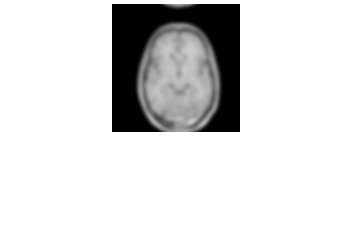

imshow(Y(:,:,i))

%% Creating a t-linear system corresponding to the deblurring problem

X_reorder = reorder_tensor(X,[m,n,p]);      %dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);

%Defining the t-linear measurement operator

A = circ_blurring_mxop(h, [m,n,p]);
B = circ_blurring_mxop(g, [m,n,p]);
C = tprod(B,A);

%Deblurring Experiments for FacTRK: Initialisation! 
X0 = zeros(n,p,m);
Xblurry = Y_reorder;


%Deblurring Experiments for TRGS
its = 5000;

[Z_reorder,res_errs] = facTBRK_err_deblurring(B,A,Y_reorder,X0,its,1,1);
[Z_reorder_blurry,res_errs_blurry] = facTBRK_err_deblurring(B,A,Y_reorder,Xblurry,its,1,1);

Z = recover_img(Z_reorder,[m,n,p]);
Z_blurry = recover_img(Z_reorder_blurry,[m,n,p]);

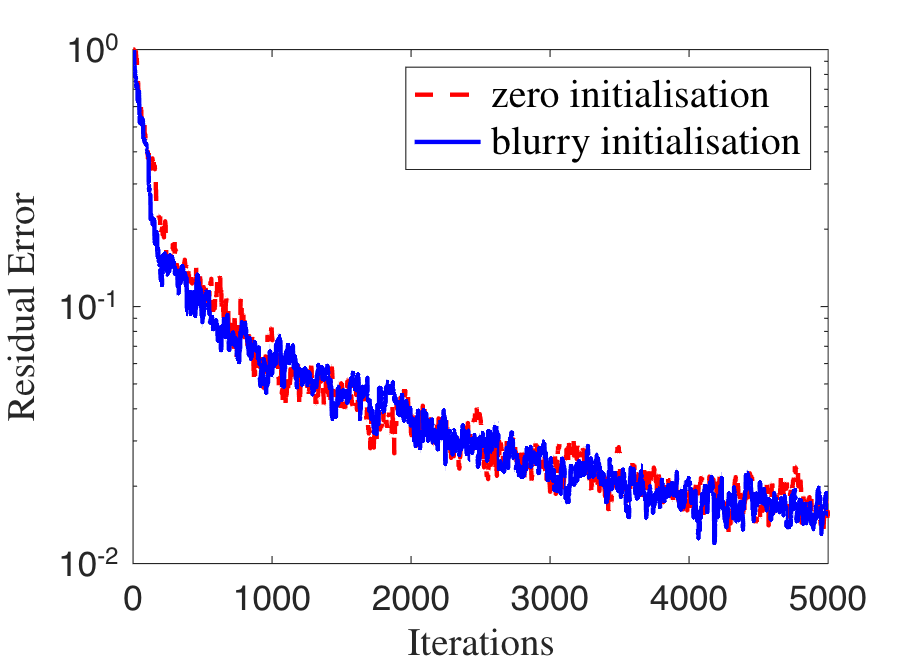

%Plotting Convergence Error Plots

figure(1);
h1 = semilogy(1:its,res_errs,'r--','LineWidth',2);
hold on
h2 = semilogy(1:its,res_errs_blurry,'b-','LineWidth',2);
hold off
xlabel('Iterations','FontSize',18,'Interpreter','latex') 
ylabel('Residual Error','FontSize',18,'Interpreter','latex') 
legend([h1(1),h2(1)],{'zero initialisation', 'blurry initialisation'},'FontSize',18,'Interpreter','latex','Location','northeast')
%title("Deblurring using FacTRK",'FontSize',18)

set(gcf,'position',[10,10,550,400])
set(gca,'FontSize',16)
savefig('figs/facTRK_deblurring_error_diff_initialization.fig')
saveas(gca,'figs/facTRK_deblurring_error_diff_initialization.png')

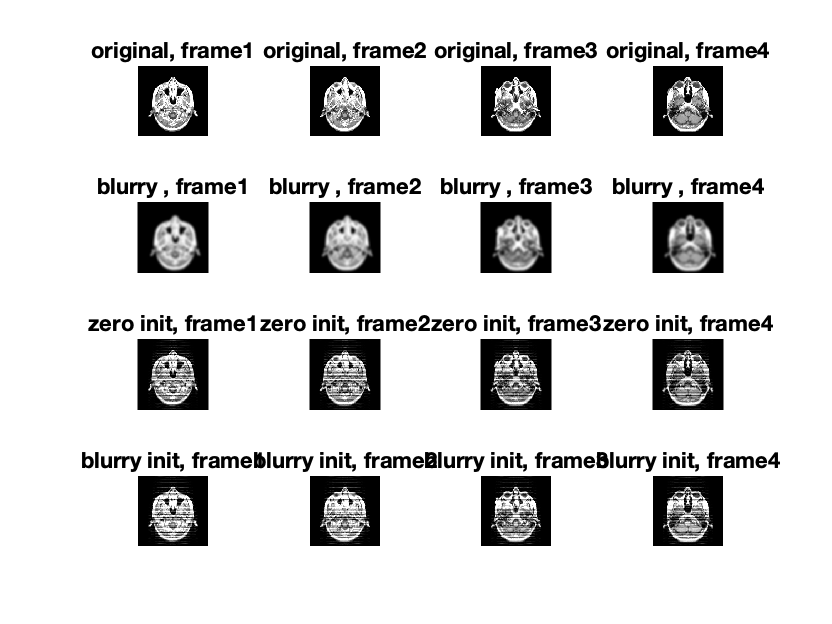

%Plotting recovered images for slices 1:4
figure(2)
it = 4;
for i = 1:it
    subplot(4,it,i)
    imshow(X(:,:,i),[0,1]);axis image off;
    title(sprintf('original, frame%d',i))

    subplot(4,it,i+it)
    imshow(Y(:,:,i),[0,1]);axis image off;
    title(sprintf('blurry , frame%d',i))

    subplot(4,it,i+2*it)
    imshow(Z(:,:,i),[0,1]);axis image off;
    title(sprintf('zero init, frame%d',i))
    
    
    subplot(4,it,i+3*it)
    imshow(Z_blurry(:,:,i));axis image off;
    title(sprintf('blurry init, frame%d',i))   
end

savefig('figs/facTRK_deblurring_diff_initialization.fig')
saveas(gcf,'figs/facTRK_deblurring_diff_initialization.png')

t = tiledlayout(5,4,'TileSpacing','none');

for i = 1:4
    nexttile;
    imagesc(X(:,:,i));colormap gray
    %axis equal
    %axis tight
    title(sprintf('frame%d',i), 'FontSize',8)
    if i == 1
        ylabel("original",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Y(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("zero init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

for i = 1:4
    nexttile;
    imagesc(Z_blurry(:,:,i));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("blurry init",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

% for i = 1:4
%     nexttile;
%     imagesc(Z_rand(:,:,i));colormap gray
%     %axis equal
%     %axis tight
%     if i == 1
%         ylabel("rand init",'FontSize',8);
%     end
%     grid off
%     set(gca,'TickLength',[0 0])
%     set(gca,'Yticklabel',[]) 
%     set(gca,'Xticklabel',[])
% end

%calculate least-norm solution
X_ln = tprod(tpinv(C),Y_reorder);
for i = 1:4
    nexttile;
    imagesc(permute(X_ln(:,:,i),[2,1,3]));colormap gray
    %axis equal
    %axis tight
    if i == 1
        ylabel("least norm",'FontSize',8);
    end
    grid off
    set(gca,'TickLength',[0 0])
    set(gca,'Yticklabel',[]) 
    set(gca,'Xticklabel',[])
end

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 8 12]); %x_width=10cm y_width=15cm

savefig('figs/facTRK_deblurring_diff_initialization.fig')
saveas(gcf,'figs/facTRK_deblurring_diff_initialization.png')